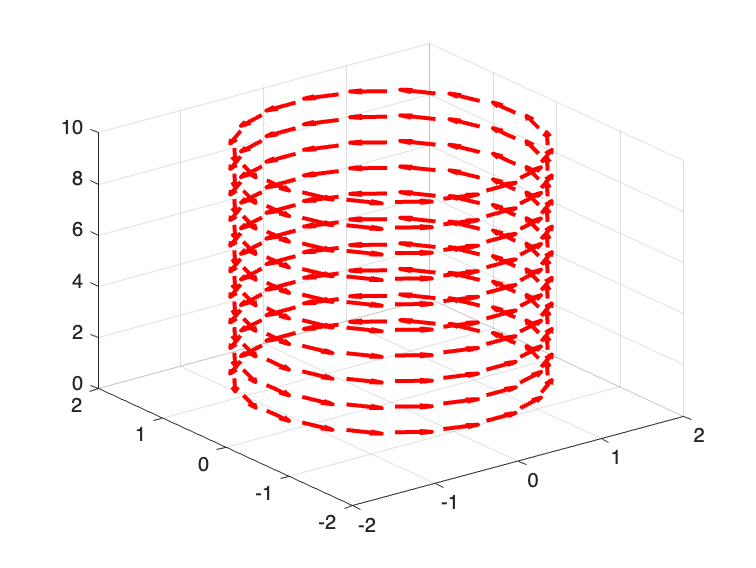

clear;
clear vars;
clear workspace;
clear outputs;

nl = 10; % number of loops
ds = 0.1; % differential

% spatial vectors
x = linspace(-5, 5, ds);
y = x;
z = x;

% vector lengths
x_size = length(x);
y_size = length(y);
z_size = length(z);

% cable thicknes
rw = 0.2;

% courrent intensity
I = 300;

% permeability coefficient
miu = 4*pi*1e-7;

% magnetic field
km = miu*I / (4*pi);

% number of points per loop
N = 20;

% radius of the wire
R = 1.5;

% step size along the Z axis
sz = 1;

% loop number
s = 1; % this is an index

% differential angle step
dtheta = (2*pi) / N;

% differential of angular length
dl = dtheta * R;

% angular vector
ang = 0:dtheta:(2*pi - dtheta);

for i = 1:nl
    Px(s:s+N-1)=R*cos(ang);
    Py(s:s+N-1)=R*sin(ang);
    Pz(s:s+N-1)= i*sz;
    dx(s:s+N-1)=-Py(s:s+N-1)*dtheta;
    dy(s:s+N-1)=Px(s:s+N-1)*dtheta;
    s=s+N;
end

dz(1:N*nl) = 0;

figure;
view(30, 30);
quiver3(Px, Py, Pz, dx, dy, dz, 0.5, '-r', 'LineWidth', 2);


% parte 2

dBx = zeros(x_size);
dBy = zeros(y_size);
dBz = zeros(z_size);

vector_r = [Px, Py, Pz];
vector_R = [x, y, z];

for i = 1:length(dBx)
    for j = 1:length(dBy)
        for k = 1:length(dBz)
            for l = 1:N*nl
                
            end
        end
    end
end

% magnitud del campo magnetico
Bmag=sqrt(dBx.^2+dBy.^2+dBz.^2); 

% no fucking idea man
centery=round(Ly/2); %?
Bx_xz=squeeze(dBx(:,centery,:)); %?
Bz_xz=squeeze(dBz(:,centery,:)); %?
Bxz=squeeze(Bmag(:,centery,:)); %?

% plotting the magnetig field. Colormap jet scheme
figure(2) 
hold on
% campo magnetico representado con gradiente de colores 'jet'
pcolor(x,z,(Bxz').^(1/3)); shading interp; colormap jet; colorbar
h1=streamslice(x,z,Bx_xz',Bz_xz',3); % draws automatically spaced streamlines from 3-D vector data U, V, and W.
set(h1,'Color', [0.8 1 0.9]); % sets the streamlines colors
xlabel 'x' % name of x label
ylabel 'z' % name of y label
title 'Magnetic field of a circular current' % The title
zz(length(ang))=0; % ? ?
